# Ejemplo de uso: wsa_dtft()

#### Transformada discreta de Fourier de una señal sinusoidal pura

Se calcula la transformada discreta de Fourier (DFT) a una señal coseno con frecuencia angular de $\frac{1}{2}$ rad/s.

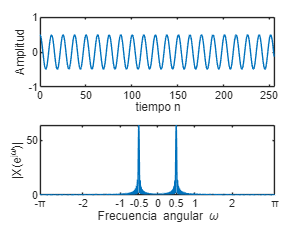

n = 0:1:255;
x_n = 0.5*cos((1/2)*n);
[X, W] = wsa_dft(x_n, 256*5);

figure;
subplot(2, 1, 1)
plot(n, x_n)
xlabel("tiempo n")
ylabel("Amplitud")
xlim([0, 256])
ylim([-1, 1])
subplot(2, 1, 2)
plot(W, abs(X))
xlim([-pi, pi])
xticks([-pi, -2, -1, -0.5, 0, 0.5, 1, 2, pi])
xticklabels({"-π", -2, -1, -0.5, 0, 0.5, 1, 2, "π"})
xlabel("Frecuencia angular \omega")
ylabel("|X(e^{j\omega})|")